% clear;
data = load('resultadosCSV_1_225mhz.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27
n_max_start = 335
T           = 5e-9;

T_buscado = 1/(2*1.225e6)

T_buscado =      4.081632653061224e-07


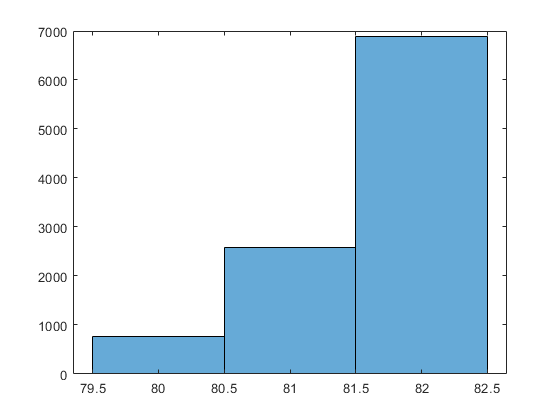

t_fino = (start-n_min_start)*tau_start - (stop-n_min_stop)*tau_stop;
t = (coarse*T) + t_fino;

histogram(coarse);

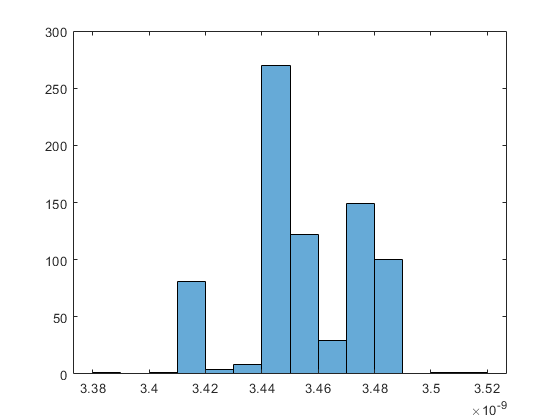


indices_80 = find(coarse==80);
indices_81 = find(coarse==81);
indices_82 = find(coarse==82);

%%Fino en 80
%%hay que sumarle una cuenta!!!
fino_80 = t_fino(indices_80);
histogram(fino_80);

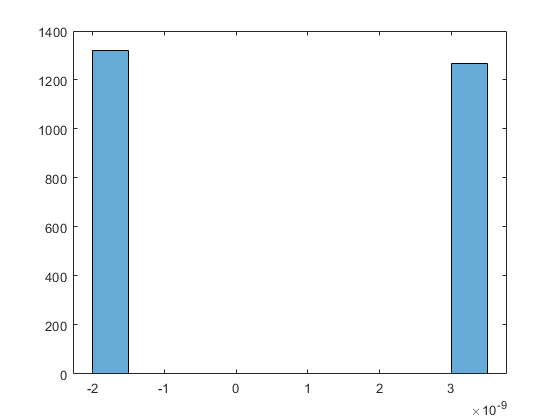


%%Fino en 81
fino_81 = t_fino(indices_81);
histogram(fino_81);

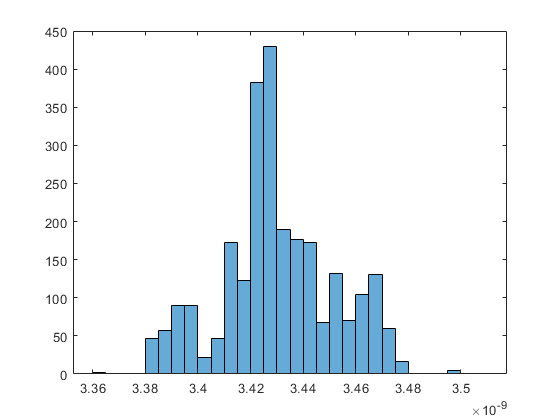

fino_81_buenos = fino_81(fino_81>0);
fino_81_malos  = fino_81(fino_81<0);
histogram([fino_81_buenos; fino_81_malos+T])

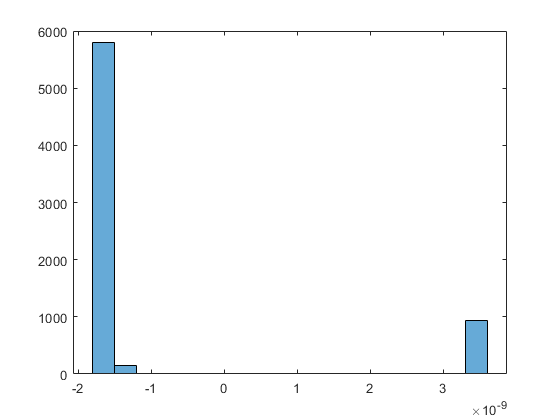


%Fino en 82
fino_82 = t_fino(indices_82);
histogram(fino_82)

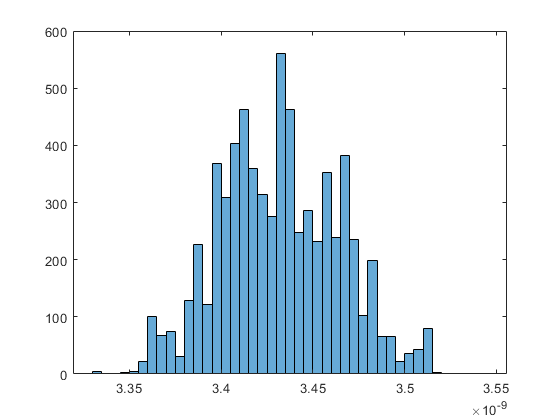

fino_82_buenos = fino_82(fino_82<0);
fino_82_malos  = fino_82(fino_82>0);
histogram([fino_82_buenos+T; fino_82_malos])

clf;
y = [fino_80; fino_81_buenos; fino_81_malos+T; fino_82_buenos+T; fino_82_malos];
presicion = std(y)

presicion =      2.981934459866811e-11


media     = mean(y)

media =      3.433217416992188e-09


coarse_correcto = 81;
N = 100;
% Clear figure
clf;

% Data vectors
data = {fino_80, fino_81_buenos, fino_81_malos+T, fino_82_buenos+T, fino_82_malos};

% Number of bins
N = 100;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = linspace(min_val, max_val, N+1);

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end

sprintf("cantidad de coarse 80: %d", length(fino_80))

ans = "cantidad de coarse 80: 767"

sprintf("cantidad de coarse 81: %d", length(fino_81))

ans = "cantidad de coarse 81: 2588"

sprintf("cantidad de coarse 82: %d", length(fino_82))

ans = "cantidad de coarse 82: 6885"

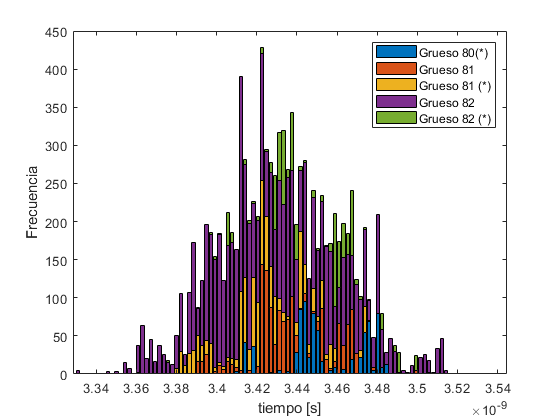

% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo [s]');
ylabel('Frecuencia');
legend({'Grueso 80(*)', 'Grueso 81', 'Grueso 81 (*)', 'Grueso 82', 'Grueso 82 (*)'});
exportgraphics(gcf,'histograma_1_225M.eps');


format long
T_buscado

T_buscado =      4.081632653061224e-07


Tiempo_final = 81*T + media

Tiempo_final =      4.084332174169922e-07


error = Tiempo_final - T_buscado

error =      2.699521108697568e-10
